clc, clear
rng('shuffle')
load BongjaNet
BuffNet1 = alexnet;
BuffNet2 = googlenet;
BuffNet3 = resnet50;

BuffSize = [227 227; 224 224; 224 224];
%bongja and bichon
Bongsimds = imageDatastore('TrainImgs','IncludeSubfolders', true, 'LabelSource', 'foldernames');
%other dogs
Dogsimds = imageDatastore('Imgs','IncludeSubfolders', true, 'LabelSource', 'foldernames');

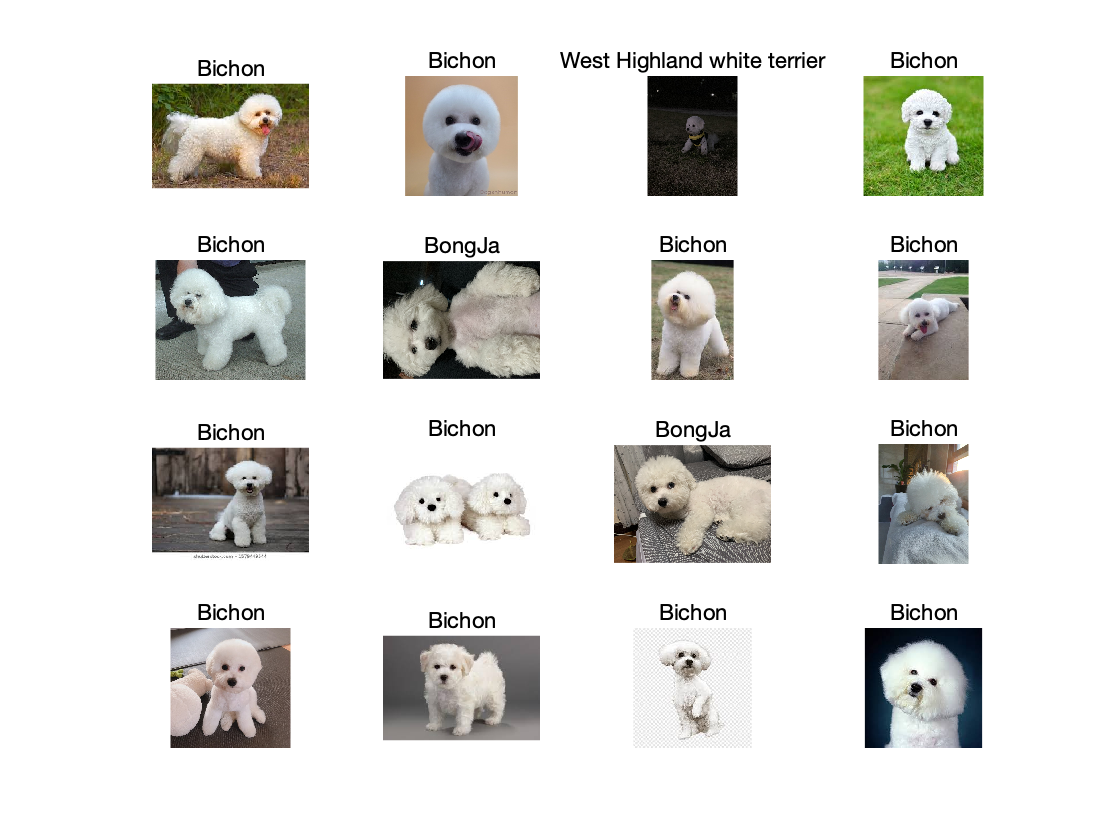

%Classify
for i=1:16
    figure(1)
    subplot(4,4, i)
    
    pick = randi([1 length(Bongsimds.Files)]);
    im = imread(Bongsimds.Files{pick});
    imshow(im)
  
    clearvars YPred;
    Entry = classify(FirstNet, im)
    if strcmp(YPred, 'Undefined')
        YPred = HierarchyPred(BuffNet3, BuffNet2, BuffNet1, BuffSize, im);
    else
        imre = imresize(im, [224 224]);
        Entry = classify(mynet, imre)
    end
    
    title(YPred);
end

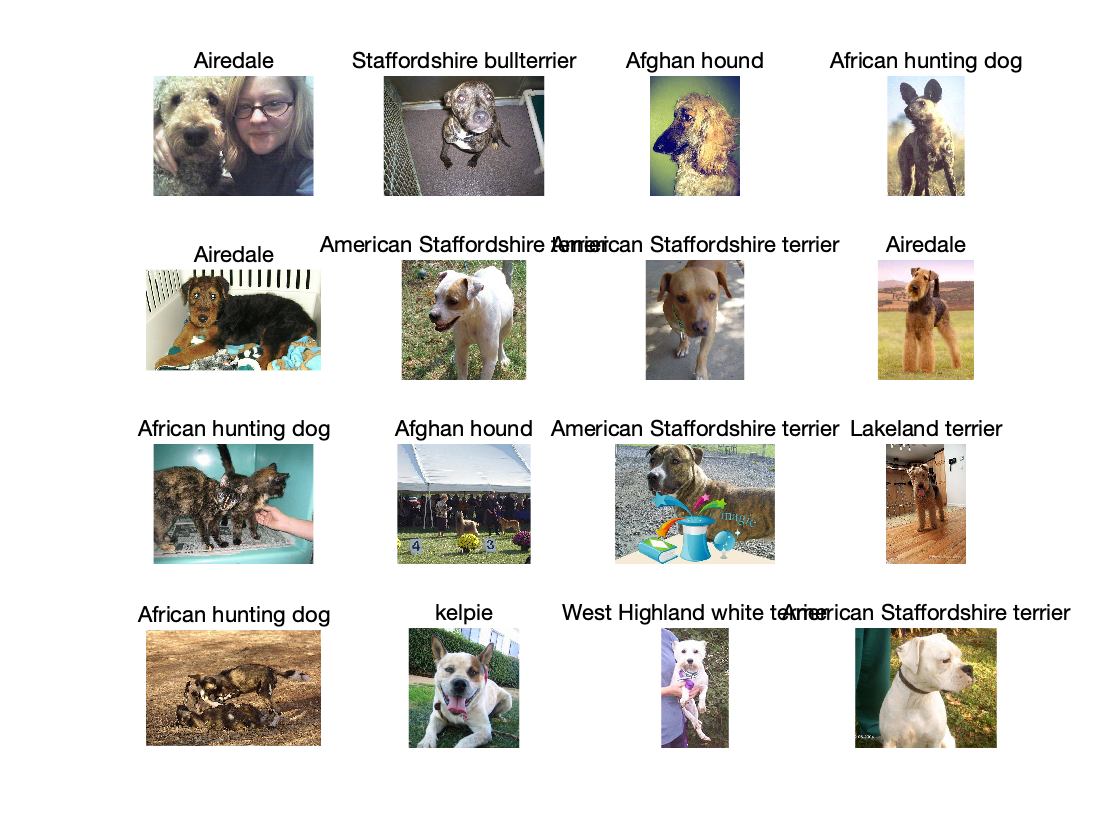

%the other dogs
for i=1:16
    figure(2)
    subplot(4,4, i)
    
    pick = randi([1 length(Bongsimds.Files)]);
    im = imread(Dogsimds.Files{pick});
    imshow(im)
  
    clearvars YPred;
    Entry = classify(FirstNet, imre)
    if strcmp(YPred, 'Undefined')
       YPred = HierarchyPred(BuffNet3, BuffNet2, BuffNet1, BuffSize, im);
    end
    
    title(YPred);
end

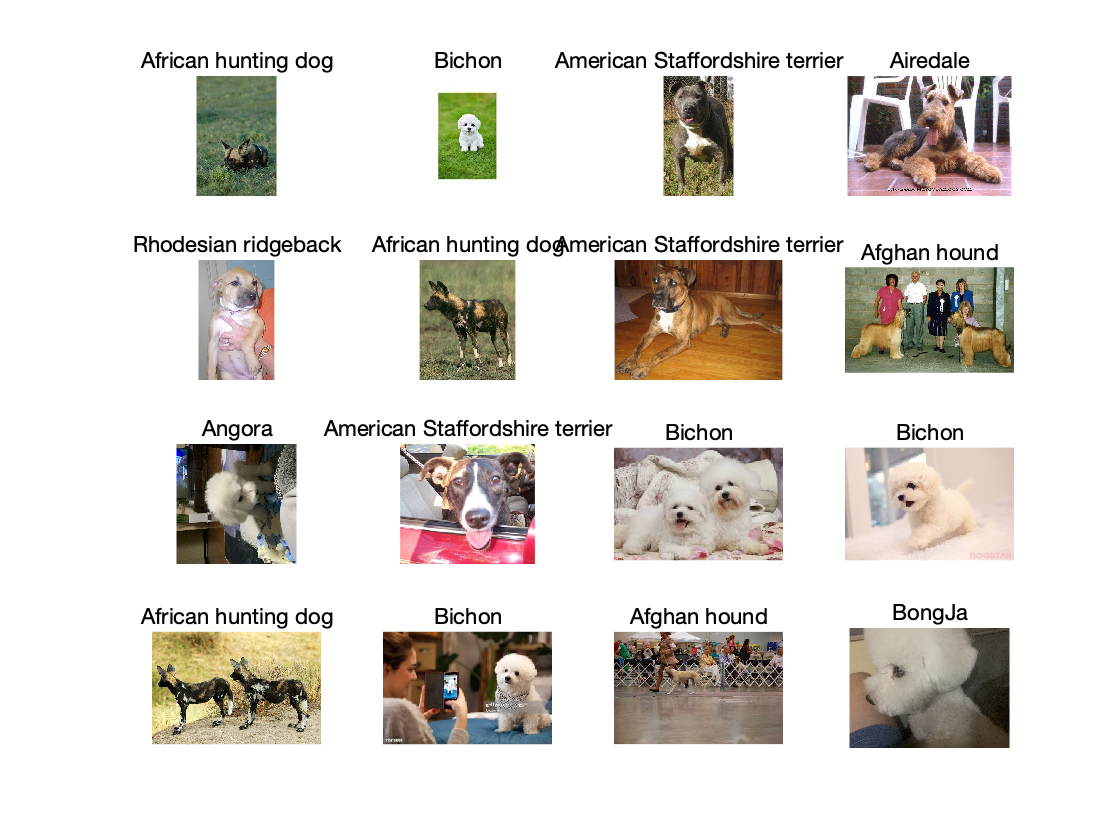

%all imgs
for i=1:16
    figure(3)
    subplot(4,4, i)
    
    pick = randi([1 length(Bongsimds.Files)     ]);
    if rand < 0.5
        im = imread(Bongsimds.Files{pick});
    else
        im = imread(Dogsimds.Files{pick});
    end

    imshow(im)
  
    clearvars YPred;
    Entry = classify(FirstNet, im)
    if strcmp(YPred, 'Undefined')
        YPred = HierarchyPred(BuffNet3, BuffNet2, BuffNet1, BuffSize, im);
    else
        imre = imresize(im, [224 224]);
        Entry = classify(mynet, imre)
    end
    
    title(YPred);
end

function YPred = HierarchyPred(net1, net2, net3, Size, im)
    NetGroup(1) = {net3};
    NetGroup(2) = {net2};
    NetGroup(3) = {net1};
    
    for i=1:length(Size)
        imre = imresize(im, Size(i,:));
        RtnVal(i) = classify(NetGroup{i}, imre);
    end
    
    CatTemp = categorical(RtnVal);
    YPred = mode(CatTemp);
end